%% unpack from saved file
imgDir = 'C:\DFiles\Geophysics\Project\Figs_Crosswell';
% imgDir = 'E:/Geophysics/Project/Crosswell/FWI_2arr';
% path to save figure
figDir = fullfile(pwd, 'Figures');

fmod1 = 'vp22_pad_smooth.mat';
mod1 = load(fullfile(imgDir, fmod1));
if mod1.fastz; vel = mod1.vp'; else; vel = mod1.vp; end
[nz, nx] = size(vel); dx = mod1.dx; dz = mod1.dz;
x = (0:nx-1)*dx; z = (0:nz-1)*dz;
% source and receiver geometry
idsrc=53;  
sx = mod1.xsrc(idsrc); sz = mod1.zsrc(idsrc); gx = mod1.xrec; gz = mod1.zrec; 
g=1:numel(gx);
%% FD params
nbc=40; nt=double(mod1.nt); dt=mod1.dt; t=(0:nt-1)*dt; isFS=false; 
s=ricker(mod1.fc,dt);
% get common shot gather
csg0 =CSG(sx, sz, gx, gz);
csg0 = csg0.getSeis(vel,nbc,dx,nt,dt,mod1.fc,isFS);

Computing shot gather at sx=0.00m sz=52.00m ... 
Elapsed time is 6.288696 seconds.


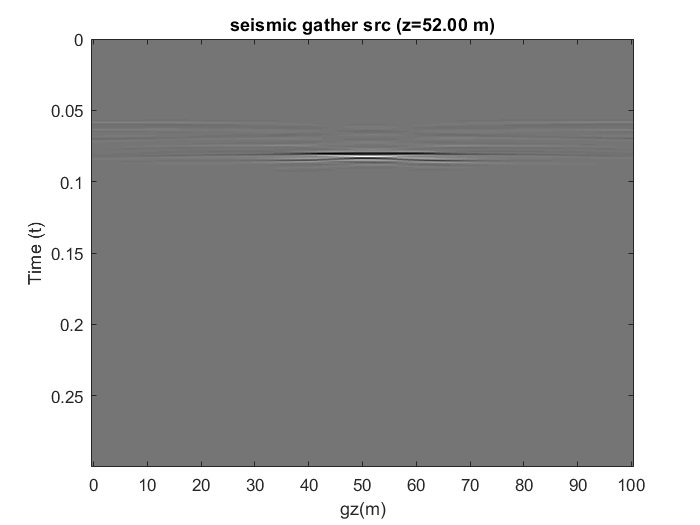

csg0.plotCSG();

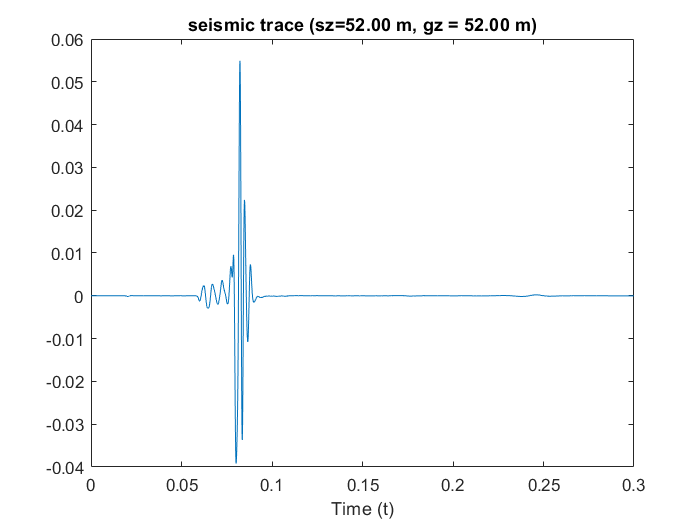

% choose trace 
idxTrace = idsrc; 
csg0.plotTrace(idxTrace);

% wavepath
tMute=0.066;
wp0 = csg0.getWP(idxTrace, tMute);

Computing wave path (sz=52.00 m, gz = 52.00 m) ... 
Elapsed time is 22.344313 seconds.


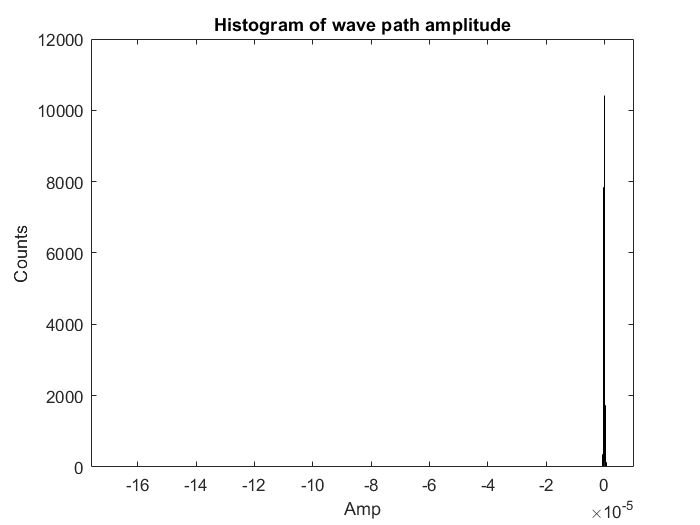

wp0.plotHist(wp0);

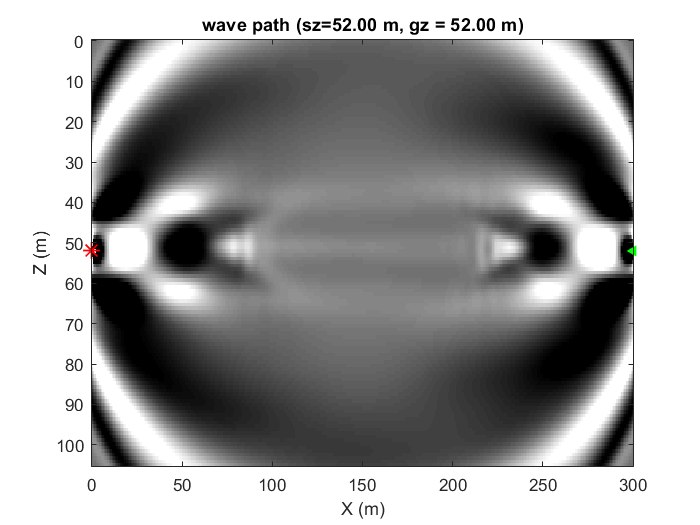

hdl=wp0.plotWP();
wp0.savefig(hdl);